# Lab - Initial value problems 1 - Runge-Kutta methods

**Topics: **Euler, Heun, midpoint method

## IVP setup

Integrate $\frac{\textrm{dy}}{\textrm{dt}}=4e^{0\ldotp 8t} -0\ldotp 5y$ from $t=0\;\textrm{to}\;2$ with step size, $h=1$.

Given initial value $y\left(t=0\right)=2$

clear, clc

t_vals = 0;
y_Exact = 0;
y_Euler = 0;
y_Heun  = 0;
y_Mid = 0;

dydt = @(t,y) 4*exp(0.8*t) - 0.5*y;
t0 = 0;
tf = 2;
h = 1;
y0 = 2;
t_vals = t0:h:tf;


## Analytical solution

syms y(t)
ode = diff(y,t) == 4*exp(0.8*t) - 0.5*y;
cond = y(t0) == y0;
yExact(t) = dsolve(ode, cond)

$$yExact(t) = \frac{2\,{\mathrm{e}}^{-\frac{t}{2}}\,\left(20\,{\mathrm{e}}^{\frac{13\,t}{10}}-7\right)}{13}$$

## Euler's method


$$y_{i+1} =y_i +f\left(t_i ,y_i \right)h$$


y_Euler = zeros(size(t_vals));
y_Euler(1) = y0;
% Step 1
phi = dydt(t_vals(1), y_Euler(1))

phi = 3

y_Euler(2) = y_Euler(1) + phi*h

y_Euler =      2     5     0


% Step 2
phi = dydt(t_vals(2), y_Euler(2))

phi = 6.4022

y_Euler(3) = y_Euler(2) + phi*h

y_Euler =     2.0000    5.0000   11.4022


## Heun's method


$$y_{i+1} =y_i +\frac{f\left(t_i ,y_i \right)+f\left(t_{i+1} ,y_{i+1}^0 \right)}{2}h$$


y_Heun = zeros(size(t_vals));
y_Heun(1) = y0;
% Step 1
slope1 = dydt(t_vals(1), y_Heun(1))

slope1 = 3

y_naught = y_Heun(1) + slope1*h

y_naught = 5

slope2 = dydt(t_vals(2), y_naught)

slope2 = 6.4022

phi = (slope1+slope2)/2

phi = 4.7011

y_Heun(2) = y_Heun(1) + phi*h

y_Heun =     2.0000    6.7011         0


% Step 2
slope1 = dydt(t_vals(2), y_Heun(2))

slope1 = 5.5516

y_naught = y_Heun(2) + slope1*h

y_naught = 12.2527

slope2 = dydt(t_vals(3), y_naught)

slope2 = 13.6858

phi = (slope1+slope2)/2

phi = 9.6187

y_Heun(3) = y_Heun(2) + phi*h

y_Heun =     2.0000    6.7011   16.3198


## Midpoint method


$$y_{i+1} =y_i +f\left(t_{i+\frac{1}{2}} ,y_{i+\frac{1}{2}} \right)h$$


y_Mid = zeros(size(t_vals));
y_Mid(1) = y0;
% Step 1
slope = dydt(t_vals(1), y_Mid(1))

slope = 3

midpoint = y_Mid(1) + slope*h/2

midpoint = 3.5000

phi = dydt((t_vals(1)+h/2), midpoint)

phi = 4.2173

y_Mid(2) = y_Mid(1) + phi*h

y_Mid =     2.0000    6.2173         0


% Step 2
slope = dydt(t_vals(2), y_Mid(2))

slope = 5.7935

midpoint = y_Mid(2) + slope*h/2

midpoint = 9.1141

phi = dydt((t_vals(2)+h/2), midpoint)

phi = 8.7234

y_Mid(3) = y_Mid(2) + phi*h

y_Mid =     2.0000    6.2173   14.9407


## Comparing results

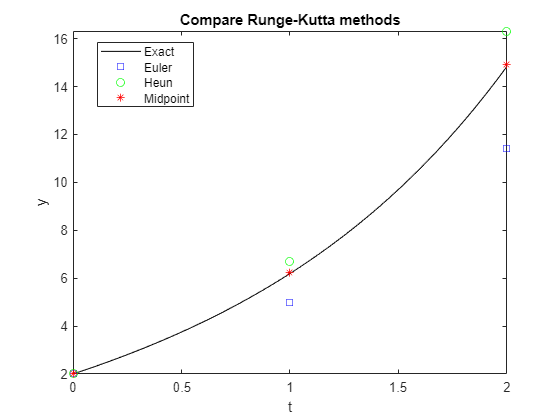

% Plotting everything 
fplot(yExact, [t0, tf], 'k')
hold on
plot(t_vals, y_Euler, 'bs', t_vals, y_Heun, 'go', t_vals, y_Mid, 'r*')
hold off
xlabel 't'
ylabel 'y'
title 'Compare Runge-Kutta methods'
legend('Exact', 'Euler', 'Heun','Midpoint', 'location','best')



% data Table
MPRTE = @(est, true) abs((true-est)/true)*100;
headings = ["t", "Exact", "Euler", "MPRTE-E", "Heun", "MPRTE-H", "Midpoint", "MPRTE-M"];

for line = 1:length(t_vals)
    if line == 1
        fprintf('%3s %8s %8s %8s %8s %8s %8s %8s\n', headings)
        fprintf('--- -------- -------- -------- -------- -------- -------- --------\n')
    end

exact = double(yExact(t_vals(line)));
    fprintf('%3d %8.4f %8.4f %7.2f%% %8.4f %7.2f%% %8.4f %7.2f%%\n', ...
        t_vals(line), exact, y_Euler(line), MPRTE(y_Euler(line), exact), ...
               y_Heun(line), MPRTE(y_Heun(line),exact), ...
               y_Mid(line), MPRTE(y_Mid(line), exact))
end

  t    Exact    Euler  MPRTE-E     Heun  MPRTE-H Midpoint  MPRTE-M


--- -------- -------- -------- -------- -------- -------- --------


  0   2.0000   2.0000    0.00%   2.0000    0.00%   2.0000    0.00%
  1   6.1946   5.0000   19.28%   6.7011    8.18%   6.2173    0.37%
  2  14.8439  11.4022   23.19%  16.3198    9.94%  14.9407    0.65%
